# Spoken digit classification using Deep Learning

Deep Learning techniques can analyze the audio and predict the spoken digit. This can be done by training a convolutional neural network. As a convolutional neural network expects images, the audio signals will be transformed into “images”. To this aim, you will use the [melSpectrogram](https://it.mathworks.com/help/audio/ref/melspectrogram.html) to extract the audio spectrogram which then can be fed into the convolutional neural network. After training the convolutional neural network, the influence of the speakers used in training on the final performance will be investigated.

Note: for the following exercise, please turn the speakers on.

Some of the functions used in this livescript require the Signal Processing Toolbox™, the Matlab Audio Toolbox™, or the Deep Learning Toolbox™. If these support packages are not installed, the functions provide the download links.

% Clear workspace and command window
clear;
clc;

## Dataset

You will use the Free Spoken Digits data set, which consists of audio recordings of digit speech and corresponding label (from 0 to 9) from 6 different speakers. The data also includes metadata such as the speaker name and its accent.

Download and extract the Free Spoken Digits data set from [https://github.com/Jakobovski/free-spoken-digit-dataset](https://github.com/Jakobovski/free-spoken-digit-dataset) or using the `download_dataset` function defined at the end of this script. Depending on your internet connection, the download process can take some time.

### Download data

This section downloads the dataset only once.

download_dataset();

### Data preparation

Use [audioDatastore](https://it.mathworks.com/help/audio/ref/audiodatastore.html) to create datastores for the training, validation, and test sets. `audioDatastore` is a versatile class to organize, read, and preprocess audio data. The audioDatastores of the three subsets are defined in the `get_audio_datastores` function at the end of this script, where the dataset split into training, validation and test sets is implemented. You will train and validate your network adopting two different dataset split strategies: naive or speaker-based.

Uncheck the `speaker_based_split` variable in order to have samples from all the speakers in both the training, validation, and test set.

Check the `speaker_based_split` variable in order to have samples of different speakers in either the training, validation, and test sets.

Note that the latter is a more challenging scenario that evaluates the generalization capability of the trained network over different speakers.

speaker_based_split = false;
[adsTrain, adsValidation, adsTest] = get_audio_datastores(speaker_based_split);

#### Samples count

Use [countEachLabel](https://it.mathworks.com/help/audio/ref/audiodatastore.counteachlabel.html) to inspect the digit breakdown of the training, validation, and test sets.

countEachLabel(adsTrain)
countEachLabel(adsValidation)
countEachLabel(adsTest)

#### Speaker count

Combine [countEachLabel](https://it.mathworks.com/help/audio/ref/audiodatastore.counteachlabel.html) and the helper function `Labesl2Speakers` (defined at the end of this script), to inspect the speaker breakdown of the training, validation, and test sets.

countEachLabel(Labesl2Speakers(adsTrain))
countEachLabel(Labesl2Speakers(adsValidation))
countEachLabel(Labesl2Speakers(adsTest))

### Training set subsampling

To train the classifier with the entire dataset and achieve the highest possible accuracy, set `reduceDatasetBy` to 0. To run this example quickly, set `reduceDatasetBy` to 2. Training set subsampling is performed for each class by using the [splitEachLabel](https://it.mathworks.com/help/audio/ref/audiodatastore.spliteachlabel.html) function.

reduceDatasetBy = 0;
if reduceDatasetBy
    % Reduce the training dataset by a factor of reduceDatasetBy
    adsTrain = splitEachLabel(adsTrain, round(numel(adsTrain.Files) / 10 / reduceDatasetBy));
    countEachLabel(adsTrain)
    countEachLabel(Labesl2Speakers(adsTrain))
end

## Audio spectrogram computation

The [melSpectrogram](https://it.mathworks.com/help/audio/ref/melspectrogram.html) function computes the Mel spectrogram of an audio signal.

### Training, Validation and Test set features

The `audio_feature_extraction`, defined at the end of this script, extracts the Mel spectrogram from all the samples of a given audio data store using the [melSpectrogram](https://it.mathworks.com/help/audio/ref/melspectrogram.html) function. In this section you will extract the features from the training, the validation, and the test sets (can take a few minutes).

featTrain = audio_feature_extraction(adsTrain);
featValidation = audio_feature_extraction(adsValidation);
featTest = audio_feature_extraction(adsTest);

## Training

### Network architecture

This section defines the convolutional neural network layers and order. This network contains Batch Normalization layers and Max Pooling layers to better extract discriminant information from the input data. Also, the Dropout layer is adopted to combat overfitting. Set the layers' parameters to change the size and the number of filters or their stride.

sz = size(featTrain);
specSize = sz(1:2);
imageSize = [specSize 1];

classes = unique(adsTrain.Labels);
numClasses = numel(classes);

dropoutProb = 0.2;
numF = 12;
layers = [
    imageInputLayer(imageSize)

    convolution2dLayer(5,numF,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(3,'Stride',2,'Padding','same')

    convolution2dLayer(3,2*numF,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(3,'Stride',2,'Padding','same')

    convolution2dLayer(3,4*numF,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(3,'Stride',2,'Padding','same')

    convolution2dLayer(3,4*numF,'Padding','same')
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3,4*numF,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2)

    dropoutLayer(dropoutProb)
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer('Classes',categorical(classes));
    ];

### Options

Change the `minibatchSize` if this does not fit in your memory. For more training options, check the [trainingOptions](https://it.mathworks.com/help/deeplearning/ref/trainingoptions.html) function documentation.

miniBatchSize = 50;
ValidationData = {featValidation, categorical(adsValidation.Labels)}; % define the validation data variable to be used during the training

options = trainingOptions('adam', ...
    'InitialLearnRate',1e-4, ...
    'MaxEpochs',30, ...
    'MiniBatchSize',miniBatchSize, ...
    'Shuffle','every-epoch', ...
    'ValidationData', ValidationData, ...
    'Plots','training-progress', ...
    'Verbose',false, ...
    'ExecutionEnvironment','cpu');

### Network training

Train the network using the [trainNetwork](https://it.mathworks.com/help/deeplearning/ref/trainnetwork.html) function. This can take some time depending on the available hardware acceleration (GPUs).

Exercise: train the network either with and without the `speaker_based_split` variable set and observe the different performance achieved on the validation set.

When `speaker_based_split` is false, you should observe a behaviour like this:

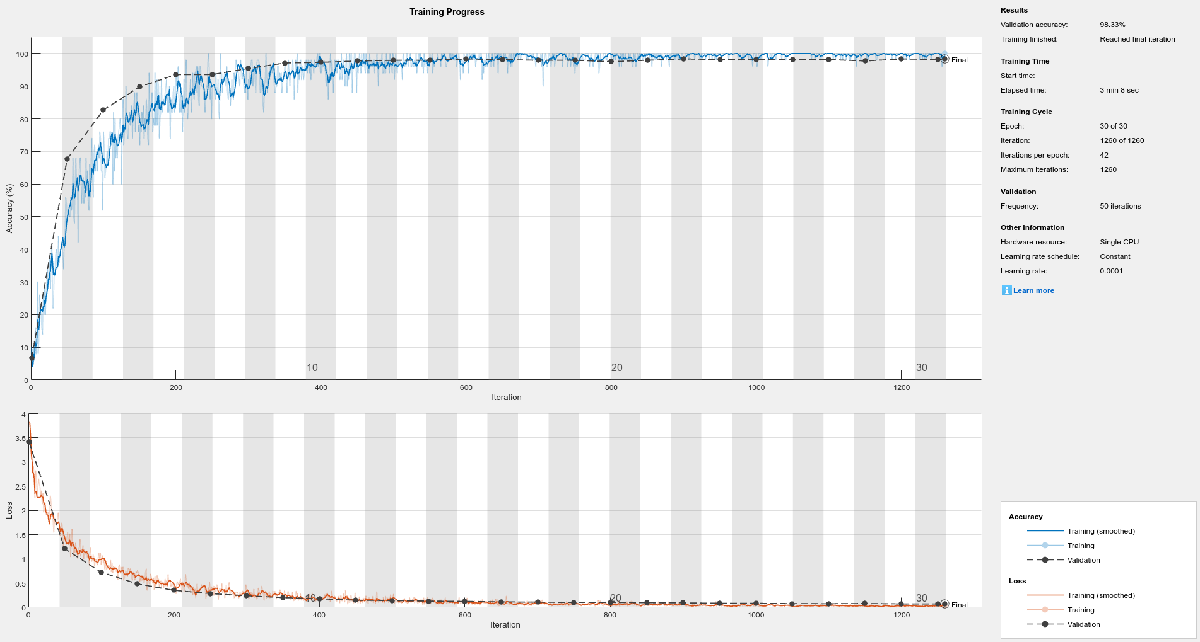

Since the training and the validation sets contain samples of the same speakers, the validation set performance is very close to that of the training set.

However, this gives no hints about the generalization capabilities of the trained network on different data (e.g. digits spoken by different speakers). In this regard, the training is prone to overfitting.

On the contrary, when `speaker_based_split` is true, you should observe a different validation performance, more similar to the following:

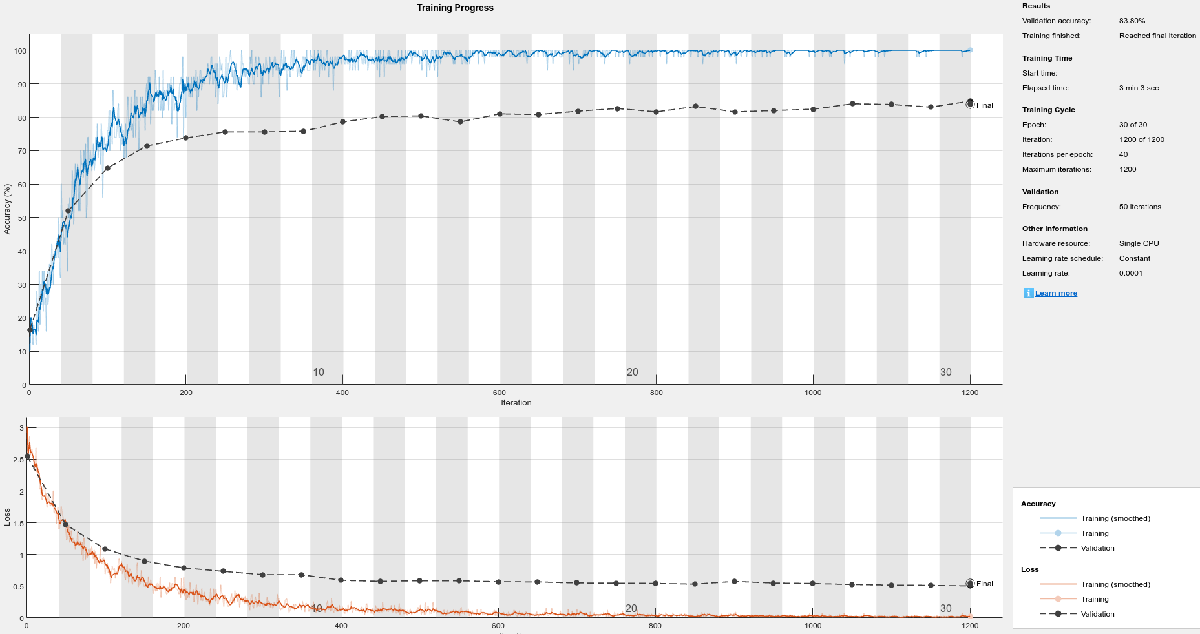

In this case, the validation performance is worse than that on the training set and reflects the performance we will have when spoken digits of new users are processed by the trained network.

trainedNet = trainNetwork(featTrain,categorical(adsTrain.Labels),layers,options);

### Test set performance

Use the trained network to predict the spoken-digit classes in the test set. This can be sensibly different from the estimated generalization accuracy obtained using the cross-validation if `speaker_based_split` is true. In that case, the performance is different from that observed on the validation set because a different speaker is considered.

predTestLabels = classify(trainedNet,featTest);
testAccuracy = sum(predTestLabels==categorical(adsTest.Labels))/numel(predTestLabels)*100
confusionchart(categorical(adsTest.Labels), predTestLabels, 'Title', 'Test set performance', 'RowSummary', "absolute");

## Further readings

Other important applications addressed by means of CNNs are [spoken commnad recognition](https://it.mathworks.com/help/deeplearning/ug/deep-learning-speech-recognition.html), [speaker recognition](https://it.mathworks.com/help/deeplearning/ug/speaker-recognition-using-x-vectors.html) and [speaker diarization](https://it.mathworks.com/help/deeplearning/ug/speaker-diarization-using-x-vectors.html).

## Helper functions

### Dataset download

This function downloads the commonvoice dataset and unzips it in the current directory.

function dataFolder = download_dataset()

% Dataset url
url = 'https://github.com/Jakobovski/free-spoken-digit-dataset/archive/refs/heads/master.zip';

% Destination directory
dataFolder = fullfile('./','free-spoken-digit-dataset-master');

% Download and extract the dataset only if the destination directory does
% not exist
if ~exist(dataFolder,'dir')
    disp('Downloading data set (20 MB) ...')
    unzip(url,'./')
end
end


### Audio data store

Use `audioDatastores` to create a datastore that contains the file names and the corresponding labels. The label is the spoken digit (from 0 to 9). This function returns the dataset split into training, validation and test subsets. Eventually, the function can perform a stratified split on the speaker identity.

Inputs:

- `speaker_based_split`: either False (all the speakers are in both the "training", "validation" or "test" sets) or True (split the speakers between the subsets).

Returns:

- `adsTrain, adsValidation, adsTest`: the audio data stores of the three subsets from which the audio signals can be loaded.

function [adsTrain, adsValidation, adsTest] = get_audio_datastores(speaker_based_split)

% Set the data folder
dataFolder = fullfile('free-spoken-digit-dataset-master','recordings');
loc = fullfile(dataFolder);

% Create the datastore containing all the samples
ads = audioDatastore(loc);
N = numel(ads.Files);

% Get label and speaker from the file name
Labels = uint8(zeros(N,1));
Speakers = cell(N,1);
for i=1:N
    [~, filename, ~] = fileparts(ads.Files{i});
    filename = strsplit(filename, '_');
    Labels(i) = str2double(filename{1});
    Speakers{i} = filename{2};
end
ads.Labels = categorical(Labels);
[unique_speakers, ~, speaker_ind] = unique(Speakers);

% Compute subset indexes
split_percentage = [.7, .15, .15];
if speaker_based_split
    Nspeakers = numel(unique_speakers);
    ind_train_speakers = 1:round(Nspeakers * split_percentage(1));
    ind_val_speakers = round(Nspeakers * split_percentage(1))+1 : round(Nspeakers * sum(split_percentage(1:2)));
    % ind_test_speakers = round(Nspeakers*.85)+1 : Nspeakers;
    
    ind_train = false(N,1);
    ind_val = false(N,1);
    ind_test = false(N,1);
    for i=1:Nspeakers
        if any(ind_train_speakers==i)
            ind_train = ind_train | speaker_ind == i;
        elseif any(ind_val_speakers==i)
            ind_val = ind_val | speaker_ind == i;
        else
            ind_test = ind_test | speaker_ind == i;
        end
    end
    
    % Split the datastore into subsets
    adsTrain = ads.subset(ind_train);
    adsValidation = ads.subset(ind_val);
    adsTest = ads.subset(ind_test);

else
    % Shuffle the datastore to have all the labels in the training set
    LabelsAndSpeakers = Labels + uint8(speaker_ind) * 10;
    ads.Labels = table(Labels, LabelsAndSpeakers);
    [adsTrain, adsValidation, adsTest] = splitEachLabel(ads, split_percentage(1), split_percentage(2), split_percentage(3),...
        'TableVariable', 'LabelsAndSpeakers');
    adsTrain.Labels = adsTrain.Labels.Labels;
    adsValidation.Labels = adsValidation.Labels.Labels;
    adsTest.Labels = adsTest.Labels.Labels;
end
end

### Labels to Speakers

For each file in the input audio data store change the respective label with the speaker name.

Inputs:

- `ads_in`: the input audio data store.

Returns:

- `ads_out`: the audio data store with speaker identity information in place of label information.

function ads_out = Labesl2Speakers(ads_in)
ads_out = copy(ads_in); % avoid modifying the input audio data store
N = numel(ads_out.Files);
Speakers = cell(N,1);
for i=1:N
    [~, filename, ~] = fileparts(ads_out.Files{i});
    filename = strsplit(filename, '_');
    Speakers{i} = filename{2};
end
ads_out.Labels = categorical(Speakers);
end

### Read data

Truncate or pad the input signal, and normalize it.

Inputs:

- `x`: the input signal.

- `L`: the number of samples to pad/truncate at.

Returns:

- `x`: the padded/truncated and normalized output signal.

function x = read_data(x, L)
if nargin < 2 || isempty(L)
    L = 8192;
end
N = numel(x);
if N > L
    % truncate
    x = x(1:L);
elseif N < L
    % pad
    pad = L-N;
    prepad = floor(pad/2);
    postpad = ceil(pad/2);
    x = [zeros(prepad,1) ; x ; zeros(postpad,1)];
end
% normalize
x = x./max(abs(x));
end

### Compute audio feature vectors

This function computes the MEL spectrogram using the [melSpectrogram](https://it.mathworks.com/help/audio/ref/melspectrogram.html) function. Please, refer to the linked documentation to set different values for the parameters like `segmentDuration`, `frameDuration`, `hopDuration`, and `numBands`.

Inputs:

- `ads`: audio data store from which the audio signals are loaded.

- `segmentDuration`: is the total duration of the speech clips (in seconds)

- `frameDuration`: the duration of each spectrogram frame

- `hopDuration`: the time shift between each spectrogram frame

- `numBands`: number of frequency bands of the filter bank

Returns:

- `feats`: the extracted audio features are stored in a matrix.

function feats = audio_feature_extraction(ads,segmentDuration,frameDuration,hopDuration,numBands)
if nargin < 2 || isempty(segmentDuration)
    segmentDuration = 8192*(1/8000);
end
if nargin < 3 || isempty(frameDuration)
    frameDuration = 0.22;
end
if nargin < 4 || isempty(hopDuration)
    hopDuration = 0.01;
end
if nargin < 5 || isempty(numBands)
    numBands = 40;
end
disp("Computing speech spectrograms...");
reset(ads);

numHops = ceil((segmentDuration - frameDuration)/hopDuration);
numFiles = length(ads.Files);
feats = zeros([numBands,numHops,1,numFiles],'single');

for i = 1:numFiles
    
    [x, info] = read(ads);
    x = read_data(x);
    fs = info.SampleRate;
    frameLength = round(frameDuration*fs);
    hopLength = round(hopDuration*fs);
    
    spec = melSpectrogram(x,fs, ...
        'Window',hamming(frameLength,'periodic'), ...
        'OverlapLength',frameLength - hopLength, ...
        'FFTLength',2048, ...
        'NumBands',numBands, ...
        'FrequencyRange',[50,4000]);
    
    % If the spectrogram is less wide than numHops, then put spectrogram in
    % the middle of X.
    w = size(spec,2);
    left = floor((numHops-w)/2)+1;
    ind = left:left+w-1;
    feats(:,ind,1,i) = spec;
    
    if mod(i,500) == 0
        disp("Processed " + i + " files out of " + numFiles)
    end
    
end

feats = log10(feats + 1e-6); % reduce high peaks

disp("...done");
end